# TD4

## Exercice 1

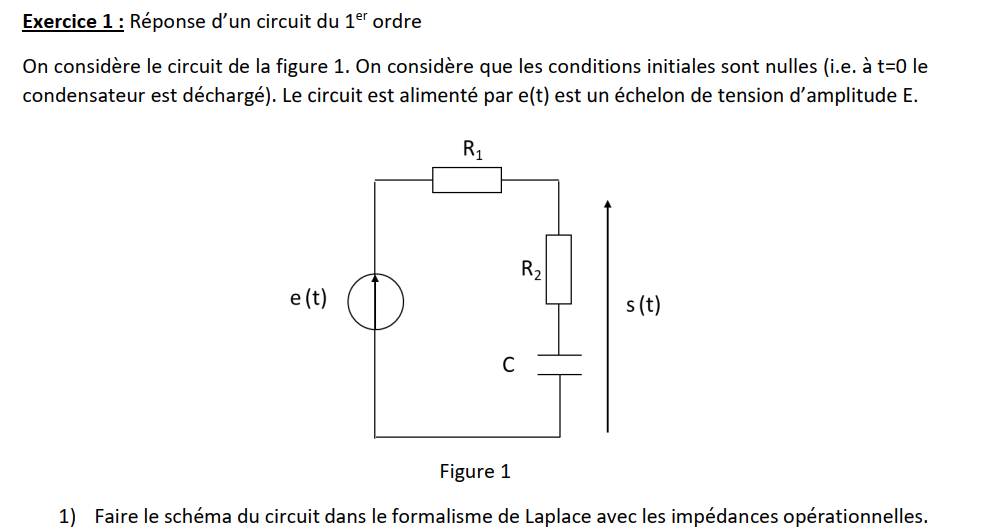

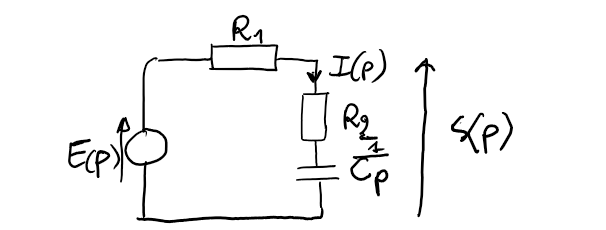

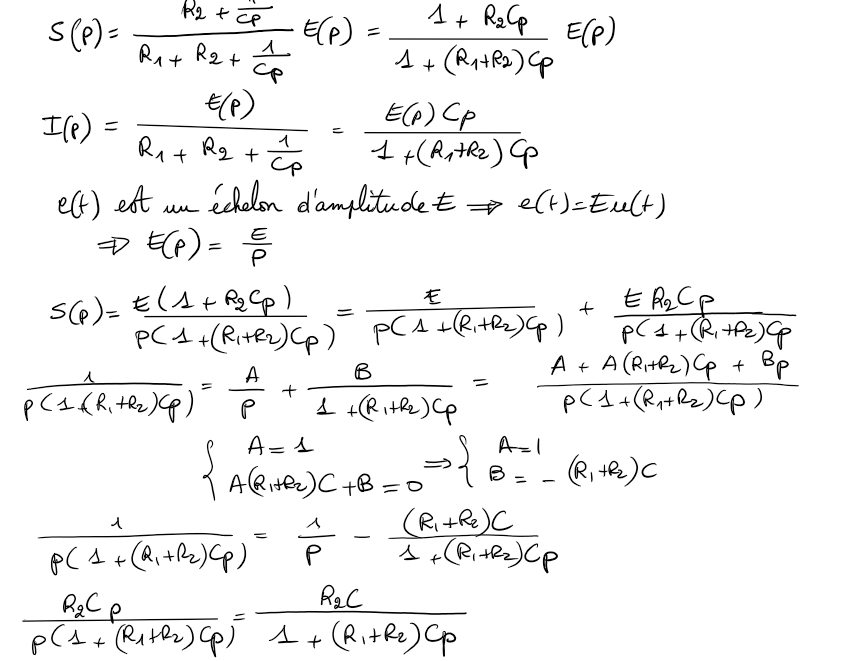

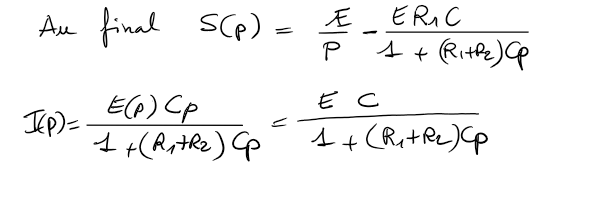

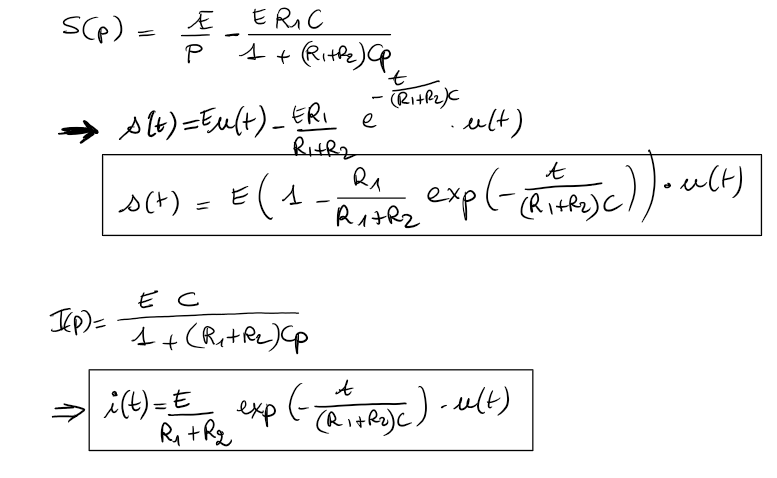

clear all
netlist={
    'R1 1 2 R1'
    'R2 2 3 R2'
    'C1 3 0 C'
    'V1 1 0 Ve'
    };
[X,name]=fspice(netlist)

** fspice 2.46  ** (c) Frederic Martinez


$$X = \left(\begin{array}{c} \mathrm{Ve}\\ \frac{\mathrm{Ve}\,\left(C\,R_{2}\,s+1\right)}{C\,R_{1}\,s+C\,R_{2}\,s+1}\\ \frac{\mathrm{Ve}}{C\,R_{1}\,s+C\,R_{2}\,s+1}\\ -\frac{C\,\mathrm{Ve}\,s}{C\,R_{1}\,s+C\,R_{2}\,s+1} \end{array}\right)$$

name = 1×4 cell array
    {'V(1)'}    {'V(2)'}    {'V(3)'}    {'I(V1)'}


Vs=X(2)

$$Vs = \frac{\mathrm{Ve}\,\left(C\,R_{2}\,s+1\right)}{C\,R_{1}\,s+C\,R_{2}\,s+1}$$

I=-X(4)

$$I = \frac{C\,\mathrm{Ve}\,s}{C\,R_{1}\,s+C\,R_{2}\,s+1}$$

syms E s
Ve=E/s

$$Ve = \frac{\text{E}}{s}$$

vs=simplify(ilaplace(subs(Vs)))

$$vs = \text{E}-\frac{\text{E}\,R_{1}\,{\mathrm{e}}^{-\frac{t}{C\,\left(R_{1}+R_{2}\right)}}}{R_{1}+R_{2}}$$

i=simplify(ilaplace(subs(I)))

$$i = \frac{\text{E}\,{\mathrm{e}}^{-\frac{t}{C\,\left(R_{1}+R_{2}\right)}}}{R_{1}+R_{2}}$$

NB : si $t_{max}=0.5\ 10^{-3}\ \rm s$ la valeur finale n'est pas atteinte ... d'où $t_{max}=0.02\ \rm s$ dans le code ci dessous.

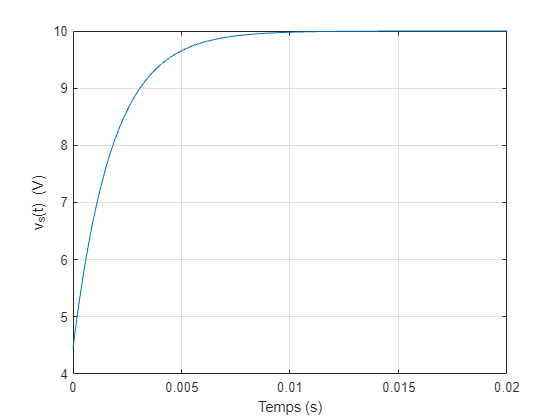

R1=10;R2=8;C=100e-6;E=10;
t=linspace(0,0.02,500);
figure
plot(t,subs(vs)),xlabel('Temps (s)'),ylabel('v_{s}(t) (V)'),grid

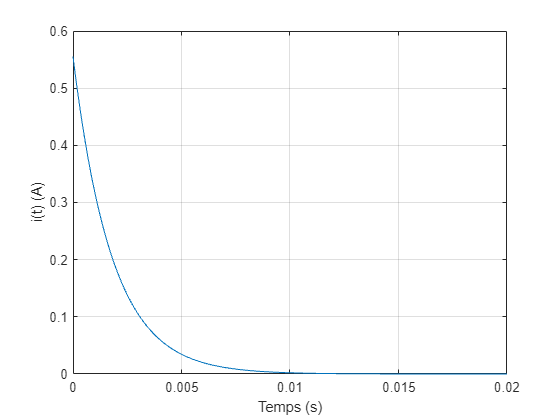

figure
plot(t,subs(i)),xlabel('Temps (s)'),ylabel('i(t) (A)'),grid

## Exercice 2

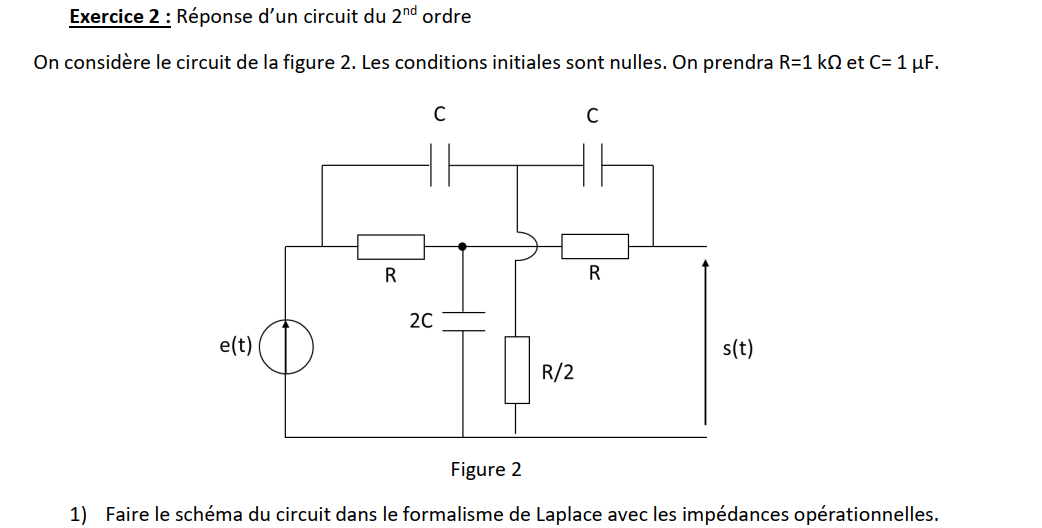

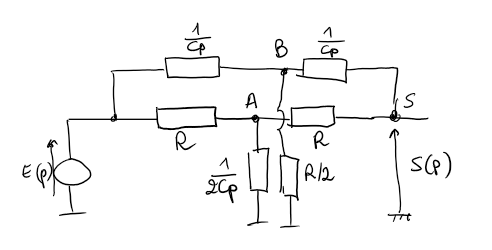

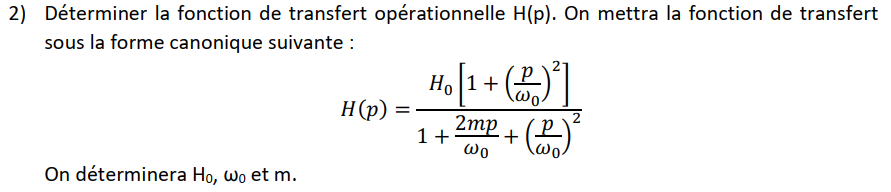

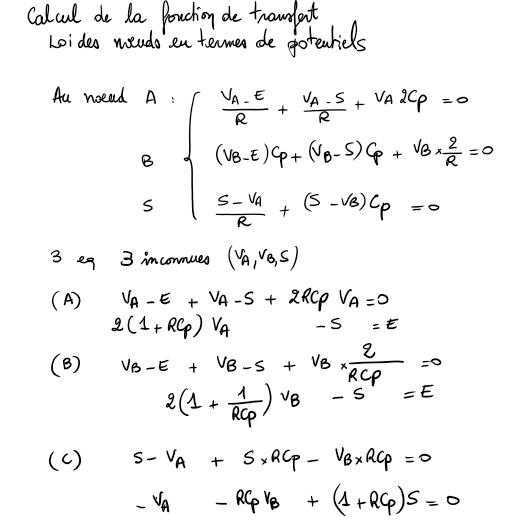

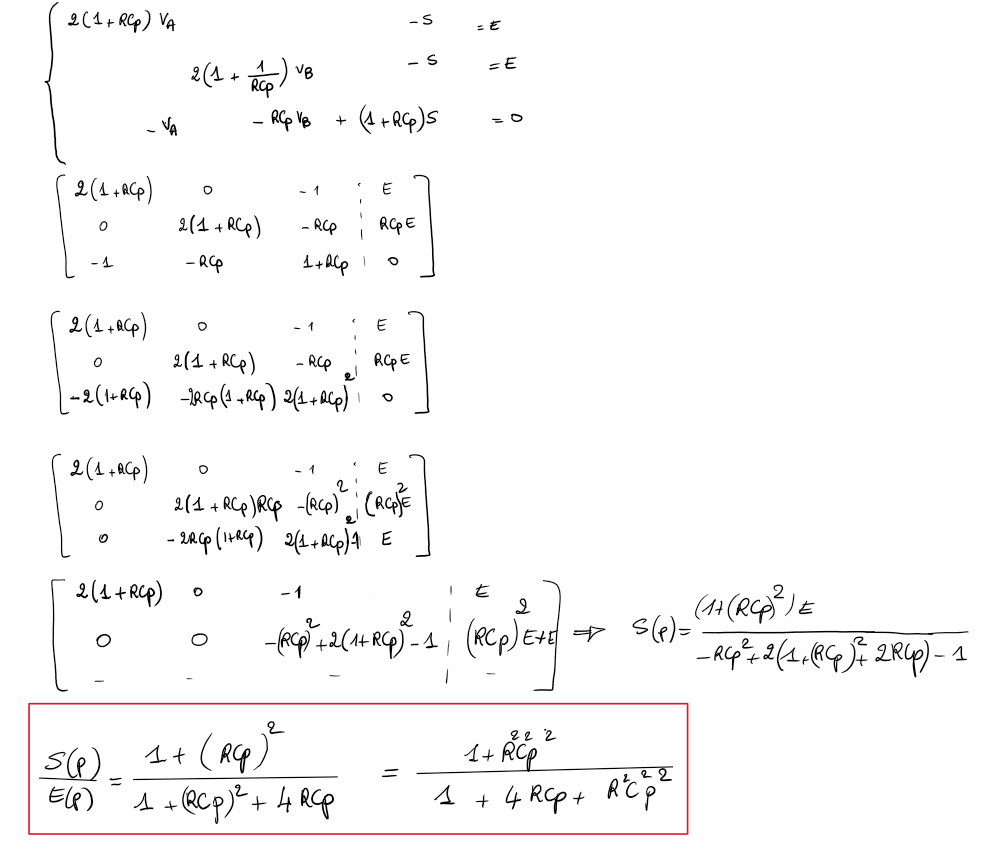

netlist={
    'R1 in A R'
    'R2 A out R'
    'C1 A 0 2*C'
    'C2 in B C'
    'C3 B out C'
    'R3 B 0 R/2'
    'V1 in 0 Ve'
    };
[X,name]=fspice(netlist)

** fspice 2.46  ** (c) Frederic Martinez


$$X = \begin{array}{l} \left(\begin{array}{c} \frac{\mathrm{Ve}\,\left(C\,R\,s+1\right)}{\sigma_{1}}\\ \frac{C\,R\,\mathrm{Ve}\,s\,\left(C\,R\,s+1\right)}{\sigma_{1}}\\ \mathrm{Ve}\\ \frac{\mathrm{Ve}\,\left(C^{2}\,R^{2}\,s^{2}+1\right)}{\sigma_{1}}\\ -\frac{4\,\mathrm{Ve}\,\left(R\,C^{2}\,s^{2}+C\,s\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=C^{2}\,R^{2}\,s^{2}+4\,C\,R\,s+1 \end{array}$$

name = 1×5 cell array
    {'V(A)'}    {'V(B)'}    {'V(in)'}    {'V(out)'}    {'I(V1)'}


H=X(4)/X(3)

$$H = \frac{C^{2}\,R^{2}\,s^{2}+1}{C^{2}\,R^{2}\,s^{2}+4\,C\,R\,s+1}$$

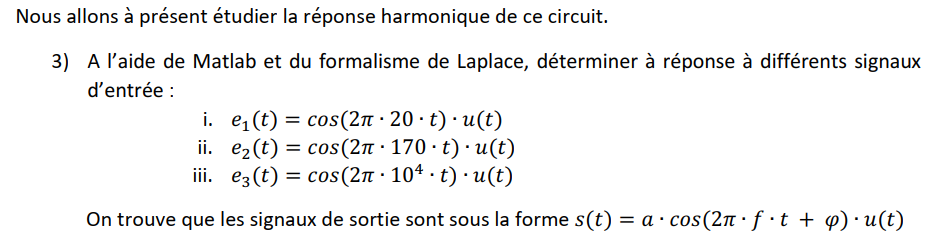

Remarque : si $e_1(t)=cos(2\pi f t) u(t)$, on est pas en régime harmonique car le régime harmonique correspond à un signal d'entrée existant de $t=-\infty$ à $t=\infty$, c'est à dire $e_1(t)=cos(2\pi f t)$

Pour calculer l'expression de la tension de sortie sera $s(t)=a cos(2\pi ft +\phi)$ et non $s(t)=a cos(2\pi ft +\phi)u(t)$.

Par définition $s(t)=\left|\underline{H}(\omega=2\pi f)\right| cos(2\pi f t+arg\left\{\underline{H}(\omega=2\pi f)\right\})$ avec $\underline{H}(\omega)=H(p=j\omega)$

syms R C w positive
s=1i*w;

On stocke dans Hb la fonction de transfert isochrone $\underline{H}(\omega)$

Hb=subs(H)   % Hb est la fct de transfert isochrone

$$Hb = -\frac{C^{2}\,R^{2}\,w^{2}-1}{-C^{2}\,R^{2}\,w^{2}+4\,C\,R\,w\,\mathrm{i}+1}$$

module de $\underline{H}(\omega)$:

module_Hb=simplify(abs(Hb),"Steps",100)

$$module\_Hb = \frac{\left|C\,R\,w-1\right|\,\left(C\,R\,w+1\right)}{\sqrt{{\left(C^{2}\,R^{2}\,w^{2}-1\right)}^{2}+16\,C^{2}\,R^{2}\,w^{2}}}$$

L'expression analytique du module dépend du signe de $RC\omega -1$ 

Si $\omega<\frac{1}{RC}$ on obtient :

syms R C w positive
assumeAlso(w<1/R/C)
simplify(module_Hb,"Steps",100)

$$ans = -\frac{C^{2}\,R^{2}\,w^{2}-1}{\sqrt{{\left(C^{2}\,R^{2}\,w^{2}-1\right)}^{2}+16\,C^{2}\,R^{2}\,w^{2}}}$$

Si $\omega>\frac{1}{RC}$ on obtient :

syms R C w positive
assumeAlso(w>1/R/C)
simplify(module_Hb,"Steps",100)

$$ans = \frac{C^{2}\,R^{2}\,w^{2}-1}{\sqrt{{\left(C^{2}\,R^{2}\,w^{2}-1\right)}^{2}+16\,C^{2}\,R^{2}\,w^{2}}}$$

Le module s'exprime analytiquement par : $\left\{\matrix{\omega<\frac{1}{RC}& \longrightarrow \left|H(\omega)\right|=-\frac{C^2 \,R^2 \,\omega^2 -1}{\sqrt{{{\left(C^2 \,R^2 \,\omega^2 -1\right)}}^2 +16\,C^2 \,R^2 \,\omega^2 }}
\cr 
\omega>\frac{1}{RC}& \longrightarrow \left|H(\omega)\right|=\frac{C^2 \,R^2 \,\omega^2 -1}{\sqrt{{{\left(C^2 \,R^2 \,\omega^2 -1\right)}}^2 +16\,C^2 \,R^2 \,\omega^2 }}}
\right.$

syms R C w positive
expand((C^2*R^2*w^2 - 1)^2 + 16*C^2*R^2*w^2)

$$ans = C^{4}\,R^{4}\,w^{4}+14\,C^{2}\,R^{2}\,w^{2}+1$$

argument de $\underline{H}(\omega)$:

### Rappel : Argument d'un nombre complexe, fonction arc-tangente et atan2

La fonction `angle` de matlab est définie par :

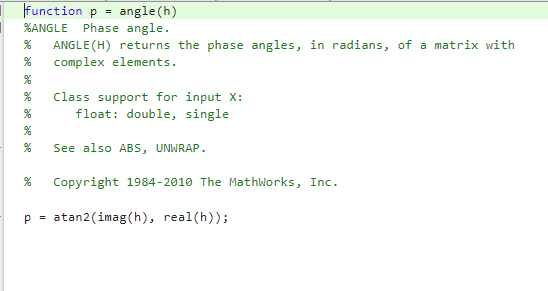

angle utilise la fonction atan2 qui définie comme la fonction tangente inverse 4 quadrans.

Four-Quadrant Inverse Tangent

Soit un point d'affixe complexe Z=X+iY.

La fonction arc tangente à quatre quadrants, atan2(Y,X), renvoie des valeurs dans l’intervalle fermé [–π, π] en fonction des valeurs de Y et de X, comme illustré dans le graphique.

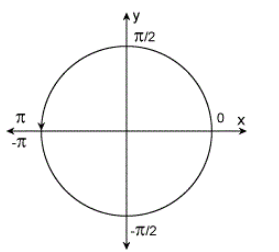

En revanche, atan(Y/X) renvoie des résultats limités à l’intervalle [–π/2, π/2], comme illustré sur le côté droit du diagramme.

Autre définition de l'arctangente 4 quadrans : $atan2(Y,X)=atan(Y/X)+\frac{\pi}{2}sign(Y)(1-sign(X))$

X=real(Hb),Y=imag(Hb)

$$X = \frac{{\left(C^{2}\,R^{2}\,w^{2}-1\right)}^{2}}{{\left(C^{2}\,R^{2}\,w^{2}-1\right)}^{2}+16\,C^{2}\,R^{2}\,w^{2}}$$

$$Y = \frac{4\,C\,R\,w\,\left(C^{2}\,R^{2}\,w^{2}-1\right)}{{\left(C^{2}\,R^{2}\,w^{2}-1\right)}^{2}+16\,C^{2}\,R^{2}\,w^{2}}$$

La partie réelle est toujours positive, on peut utiliser la fonction arctangente car l'angle sera toujours entre $-\pi/2$ et $\pi/2$

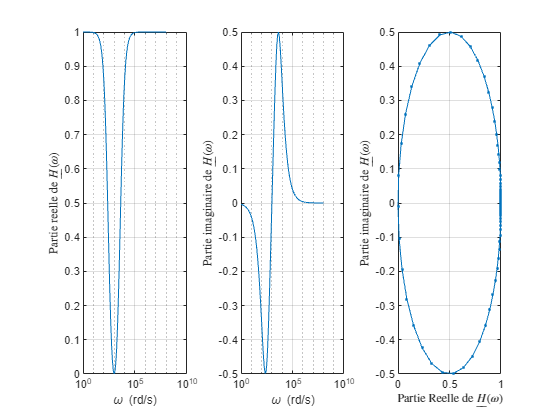

R=1000;C=1e-6;w=logspace(0,8,100);
Hb_=subs(Hb);
figure
subplot(1,3,1)
semilogx(w,real(Hb_)),ylabel('Partie reelle de $\underline{H}(\omega)$','Interpreter','latex'),grid,xlabel('\omega (rd/s)')
subplot(1,3,2)
semilogx(w,imag(Hb_)),ylabel('Partie imaginaire de $\underline{H}(\omega)$','Interpreter','latex'),grid,xlabel('\omega (rd/s)')
subplot(1,3,3)
plot(real(Hb_),imag(Hb_),'.-');xlabel('Partie Reelle de $\underline{H}(\omega)$','Interpreter','latex'),ylabel('Partie imaginaire de $\underline{H}(\omega)$','Interpreter','latex'),grid

Y/X

$$ans = \frac{4\,C\,R\,w}{C^{2}\,R^{2}\,w^{2}-1}$$


$$Arg\{\underline{H}(\omega)\}=arctan\left(\frac{4\,C\,R\,\omega}{C^2 \,R^2 \,\omega^2 -1}\right)$$


### Utilisation du calcul symbolique

Si on ne fait aucune hypothèse sur la valeur de $\omega$ par rapport à $\frac{1}{RC}$, on obtient pas d'expression simplifiée.

syms R C w 
simplify(angle(Hb))

$$ans = \text{angle}\left(-\frac{C^{2}\,R^{2}\,w^{2}-1}{-C^{2}\,R^{2}\,w^{2}+4\,C\,R\,w\,\mathrm{i}+1}\right)$$

En utilisant comme arctangente 4 quadrans la relation : $atan2(Y,X)=atan(Y/X)+\frac{\pi}{2}sign(Y)(1-sign(X))$

arg=atan(Y/X)+pi/2*sign(Y)*(1-sign(X))

$$arg = \begin{array}{l} \mathrm{atan}\left(\frac{4\,C\,R\,w}{\sigma_{2}}\right)-\frac{\pi \,\mathrm{sign}\left(\frac{C\,R\,w\,\sigma_{2}}{\sigma_{1}}\right)\,\left(\mathrm{sign}\left(\frac{{\sigma_{2}}^{2}}{\sigma_{1}}\right)-1\right)}{2}\\ \mathrm{where}\\ \sigma_{1}={\sigma_{2}}^{2}+16\,C^{2}\,R^{2}\,w^{2}\\ \sigma_{2}=C^{2}\,R^{2}\,w^{2}-1 \end{array}$$

assumeAlso(R,{'real','positive'})
assumeAlso(C,{'real','positive'})

assumeAlso(w,'real')
assumptions

$$ans = \left(\begin{array}{ccc} w\in \mathbb{R} & 0<C & 0<R \end{array}\right)$$

simplify(angle(Hb))

$$ans = \text{atan2}\left(4\,C^{3}\,R^{3}\,w^{3}-4\,C\,R\,w,C^{4}\,R^{4}\,w^{4}-2\,C^{2}\,R^{2}\,w^{2}+1\right)$$

simplify(arg)

$$ans = \mathrm{atan}\left(\frac{4\,C\,R\,w}{C^{2}\,R^{2}\,w^{2}-1}\right)$$

Comparée à la solution trouvée "à la main" , on retrouve $Arg\{\underline{H}(\omega)\}=arctan\left(\frac{4\,C\,R\,\omega}{C^2 \,R^2 \,\omega^2 -1}\right)$

Application numérique


$$e_1(t)=cos(2\pi 20 t) \Longrightarrow \underline{e_1}(\omega=2\pi 20)=1 
\\ \Longrightarrow  \underline{s}(\omega=20\pi 20)=\underline{H}(\omega=20\pi 20)\times \underline{e_1}(\omega=20\pi 20)
\\ \Longrightarrow s(t)=\left|\underline{H}(\omega=20\pi 20)\times \underline{e_1}(\omega=20\pi 20)\left|cos(2\pi 20 t+arg\left((\underline{H}(\omega=20\pi 20)\times \underline{e_1}(\omega=20\pi 20)\right)$$


R=1000;C=1e-6;w=2*pi*20;
double(subs(Hb))

ans = 0.7931 - 0.4051i

Calcul du module :

double(abs(subs(Hb)))

ans = 0.8906

Calcul de l'argument (en radians)

double(angle(subs(Hb)))

ans = -0.4722


$$e_1(t)=cos(2\pi 20 t) \Longrightarrow s(t)=0.89cos(2\pi 20 t-0.47)$$



$$e_2(t)=cos(2\pi 170 t)$$


R=1000;C=1e-6;w=2*pi*170;
double(subs(Hb))

ans = 0.0011 + 0.0329i

Calcul du module :

double(abs(subs(Hb)))

ans = 0.0330

Calcul de l'argument (en radians)

double(angle(subs(Hb)))

ans = 1.5378


$$e_2(t)=cos(2\pi 170 t) \Longrightarrow s(t)=0.03cos(2\pi 170 t+0.153)$$



$$e_3(t)=cos(2\pi 10^4 t)$$


R=1000;C=1e-6;w=2*pi*1e4;
double(subs(Hb))

ans = 0.9960 + 0.0634i

Calcul du module :

double(abs(subs(Hb)))

ans = 0.9980

Calcul de l'argument (en radians)

double(angle(subs(Hb)))

ans = 0.0636


$$e_3(t)=cos(2\pi 10^4 t) \Longrightarrow s(t)=0.99cos(2\pi 10^4 t+0.06)$$


4) Tracer le diagramme de Bode de ce circuit. On s’aidera de l’annexe 3. A quel type de filtre correspond ce circuit ?  

syms R C w
Hb=-(C^2*R^2*w^2 - 1)/(- C^2*R^2*w^2 + 4*C*R*w*sym(1i) + 1)

$$Hb = -\frac{C^{2}\,R^{2}\,w^{2}-1}{-C^{2}\,R^{2}\,w^{2}+4\,C\,R\,w\,\mathrm{i}+1}$$

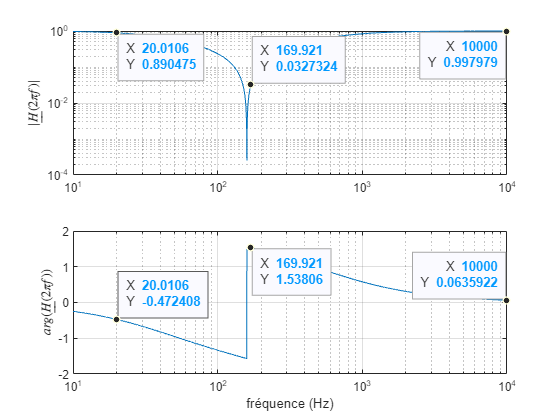

R=1000;C=1e-6;f=logspace(1,4,5000);
w=2*pi*f;
figure
subplot(2,1,1)
loglog(f,abs(subs(Hb))),grid,ylabel('$\left|\underline{H}(2\pi f)\right|$','Interpreter','latex')
ax = gca;
chart = ax.Children(1);
datatip(chart,20,0.89);
datatip(chart,170,0.033);
datatip(chart,1e4,0.99);
subplot(2,1,2)
semilogx(f,angle(subs(Hb))),grid,xlabel('fréquence (Hz)'),ylabel('$arg\left(\underline{H}(2\pi f)\right)$','Interpreter','latex')

ax2 = gca;
chart2 = ax2.Children(1);
datatip(chart2,1e4,0.06664);
datatip(chart2,170,1.537);
datatip(chart2,20,-0.4736);

Il s'agit d'un filtre réjecteur de bande.

5) Utiliser le diagramme de Bode pour estimer 𝑎 et 𝜑 pour les trois signaux d’entrée  

Avec les curseurs aux fréquences 20 Hz, 170 Hz et $10^4$ Hz, on retrouve les expressions calculées précedemment.